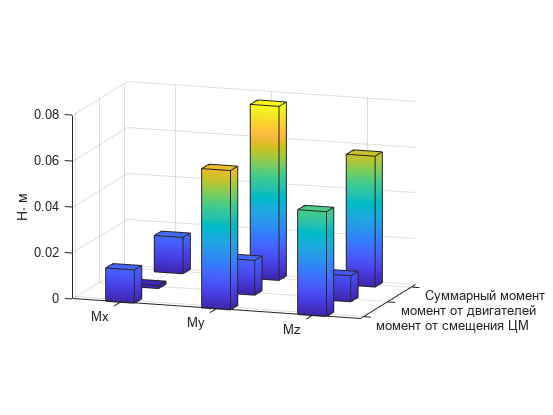

data = [
    0.0145, 0.0013, 0.0158;  % Mx
    0.0606, 0.0151, 0.0757;  % My
    0.0456, 0.0113, 0.0569;  % Mz
];

% Подписи осей
categories = {'Mx', 'My', 'Mz'};
series = {'момент от смещения ЦМ', 'момент от двигателей', 'Суммарный момент'};

% 3D столбчатая диаграмма
figure;
bar3(data, 0.3);  % 0.4 — это ширина столбика (от 0 до 1)

% Получить массив "детей" (столбцов)
h = get(gca, 'Children');

% Перебрать каждый бар (3 группы столбцов)
for k = 1:length(h)
    zdata = get(h(k), 'ZData');
    set(h(k), ...
        'CData', zdata, ...
        'FaceColor', 'interp');
end

set(gca, 'XTickLabel', series);
set(gca, 'YTick', 1:3, 'YTickLabel', categories);



view([-71.3565 11.8043])

zlabel('Н\cdot м');

saveas(gcf, 'moments_chart.eps')


grid on;